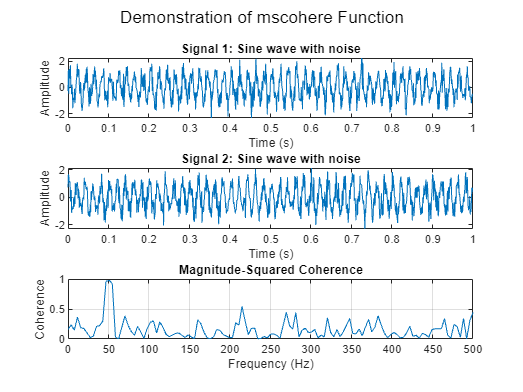

% MATLAB code to demonstrate the use of mscoherence

% Parameters
Fs = 1000;           % Sampling frequency (Hz)
T = 1;               % Duration (seconds)
t = 0:1/Fs:T-1/Fs;   % Time vector

% Generate two sine waves with some noise
f1 = 50;              % Frequency of the first sine wave (Hz)
f2 = 50;              % Frequency of the second sine wave (Hz)

% Signal 1: Sine wave + noise
signal1 = sin(2*pi*f1*t) + .5*randn(size(t));

% Signal 2: Sine wave + noise (with some phase shift)
signal2 = sin(2*pi*f2*t + pi/4) + .5*randn(size(t));

% Calculate magnitude-squared coherence
[coh, f] = mscohere(signal1, signal2, [], [], [], Fs,"mimo");

% Plot the signals
figure;
subplot(3,1,1);
plot(t, signal1);
title('Signal 1: Sine wave with noise');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, signal2);
title('Signal 2: Sine wave with noise');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the magnitude-squared coherence
subplot(3,1,3);
plot(f, coh);
title('Magnitude-Squared Coherence');
xlabel('Frequency (Hz)');
ylabel('Coherence');
grid on;

% Enhance the overall figure
sgtitle('Demonstration of mscohere Function');